# PRÁCTICA 7

## DIAGRAMA DE BLOQUES Y DATOS

% a) Archivo con grabación de audio (d(n))
[d, Fs] = audioread('PDS_P7_3B_LE2_G2_d_n.wav');
%sound(d, Fs);

% b) Archivo con ruido de fondo (x(n))
[x, Fs] = audioread('PDS_P7_3B_LE2_G2_x_n.wav');
%sound(x, Fs);

load PDS_P7_3B_LE2_G2.mat

## IMPLEMENTACIÓN DEL ALGORITMO LMS

% a) y b) Algoritmo

%Inicializo los arrays
w = zeros(length(x)-M+1,M+1); %Coeficientes adaptativos (M+1 = 11)
e = zeros(length(x)-M,1); %Errores
y = zeros(length(x)-M,1); %Salida del filtro

for i = M+1:length(x) 
    x_i = x(i:-1:i-M); % Últimas M+1 muestras
    y(i,1) = w(i,:)*x_i; % Salida 
    e(i,1) = d(i)-y(i); % Error 
    w(i+1,:) = w(i,:)+2*mu*e(i)*x_i'; % Nuevos coeficientes
end



% c) Valor de mu

%Compruebo los autovalores de la matriz de autocorrelaciones para cada
%entrada del filtro x_i.

lambda_max = zeros(length(x)-M,1); %Inicializo el array
lambda_min = zeros(length(x)-M,1); %Inicializo el array
for i = M+1:length(x)

    %Matriz de correlaciones para cada array de x_i que entra al filtro
    R = x(i:-1:i-M)*x(i:-1:i-M)'; 

    %Autovalores de cada matriz de correlaciones. Como mu<1/lambda, 
    %escogemos el máximo para que converja en todas las dimensiones (hay 11)
    lambda_max(i-M,1) = max(eig(R)); 
    lambda_min(i-M,1) = min(eig(R)); 

end

%Se vuelve a escoger el máximo de entre todos los autovalores para que
%converja en toda la señal
lambda_max = max(lambda_max);
lambda_min = min(lambda_min);

%Para que nuestros coeficientes converjan, 0 < mu < 1/lambda_max

disp(mu);

    0.0121



disp(1/lambda_max);

    0.4075




%Se cumple que 0 < mu < 1/lambda_max

%Además, 0 < mu < 1/lambda_max -> converge sin oscilaciones (confirmar en multidim)



%%% A MAYORES: (CONFIRMAR QUE ESTÁ BIEN HECHO, OTRO LAMBDA_MIN??)

%Para calcular la velocidad de convergencia global he de calcular los autovalores 
%de la matriz de autocorrelación de la señal de entrada al filtro adaptativo. 
%La velocidad de convergencia global se mide a partir de la semejanza de los 
%valores propios

disp(lambda_min/lambda_max);

  -2.4114e-16




%Valor muy cercano a cero, convergencia muy lenta


sound(e, Fs);

## ANÁLISIS DE LOS RESULTADOS

t = 0:1/Fs:(length(x)-1)*(1/Fs)

t =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011


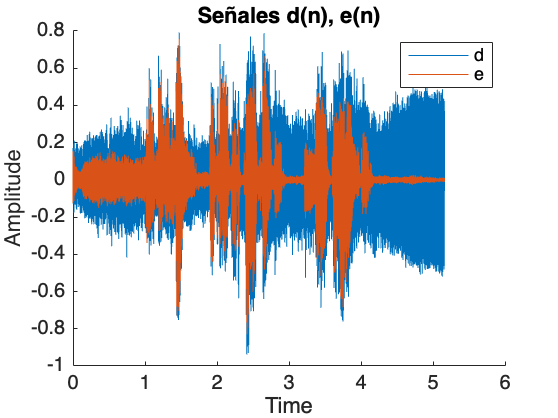


% a)
figure
hold on
plot(t,d)
plot(t,e)
hold off
title("Señales d(n), e(n)")
xlabel("Time")
ylabel("Amplitude")
legend("d", "e")

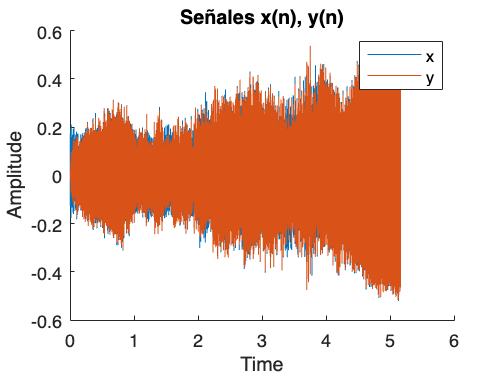


% b)
figure
hold on
plot(t,x)
plot(t,y)
hold off
title("Señales x(n), y(n)")
xlabel("Time")
ylabel("Amplitude")
legend("x", "y")

% c)
D = fft(d, length(d)) / length(d);
fd = linspace(-Fs/2, Fs/2, length(d));

X = fft(x, length(x)) / length(x);
fx = linspace(-Fs/2, Fs/2, length(x));

Y = fft(y, length(y)) / length(y);
fy = linspace(-Fs/2, Fs/2, length(y));

E = fft(e, length(e)) / length(e);
fe = linspace(-Fs/2, Fs/2, length(e));

hold off

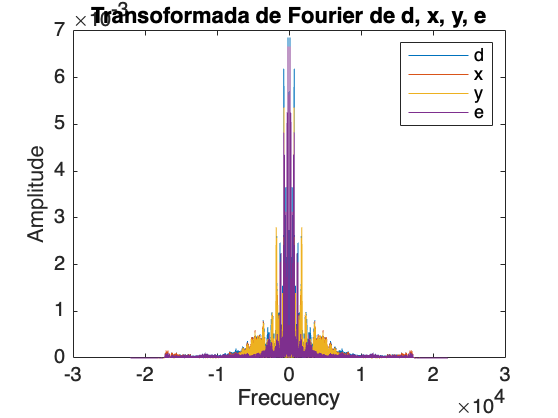

plot(fd, fftshift(abs(D)));
hold on
plot(fx, fftshift(abs(X)));
plot(fy, fftshift(abs(Y)));
plot(fe, fftshift(abs(E)));
title("Transoformada de Fourier de d, x, y, e")
ylabel("Amplitude")
xlabel("Frecuency")
legend("d", "x", "y", "e")

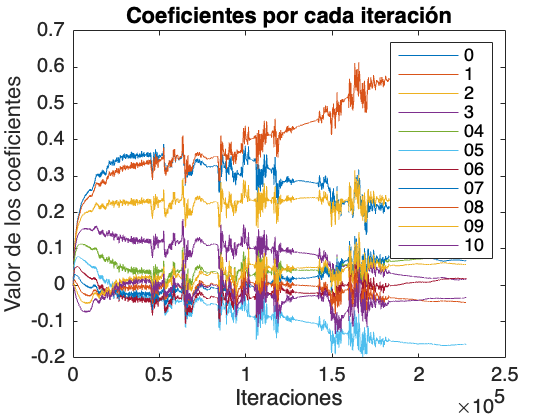



% d)
figure
plot(w)
title("Coeficientes por cada iteración")
xlabel("Iteraciones")
ylabel("Valor de los coeficientes")


% e) Algunos de los coeficientes convergen hacia el 0, pero no todos. Mirar gráfica
% apartado d)